addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 1: part b) entire quadratic lagrange interpolation

xData = [9 9.5 11];
yData = [2.1972 2.2513 2.3979];

[poly, Ls] = interpLagrange(xData, yData);
poly

$$poly = -0.005233333333\,x^{2}+0.2050166667\,x+0.77595$$

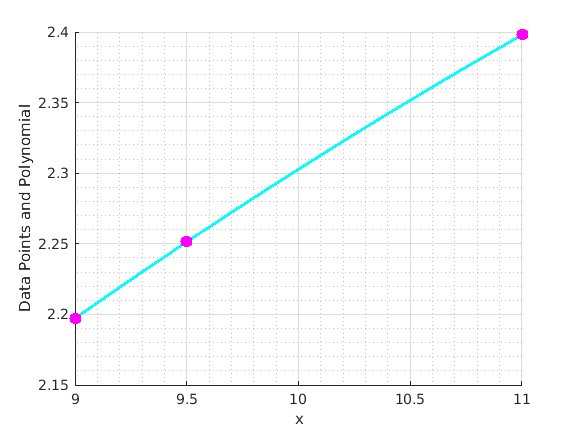

plotPoly(xData, yData, [min(xData), max(xData)], poly)

% check that my answers are right: 
syms x 
Ls(1)

$$ans = x^{2}-\frac{41\,x}{2}+\frac{209}{2}$$

L1 = expand((x - 9.5)*(x - 11)/((9-9.5)*(9-11)))

$$L1 = x^{2}-\frac{41\,x}{2}+\frac{209}{2}$$

isequal(Ls(1), L1)

ans = logical
   1


%
Ls(2)

$$ans = -\frac{4\,x^{2}}{3}+\frac{80\,x}{3}-132$$

L2 = expand((x-9)*(x-11)/((9.5-9)*(9.5-11)))

$$L2 = -\frac{4\,x^{2}}{3}+\frac{80\,x}{3}-132$$

%
Ls(3)

$$ans = \frac{x^{2}}{3}-\frac{37\,x}{6}+\frac{57}{2}$$

L3 = expand( (x-9)*(x-9.5)/((11-9)*(11-9.5)) )

$$L3 = \frac{x^{2}}{3}-\frac{37\,x}{6}+\frac{57}{2}$$

poly

$$poly = -0.005233333333\,x^{2}+0.2050166667\,x+0.77595$$

% estimate of ln(9.2)
calc(poly, 9.2)

$$ans = 2.2191539999999999998453459326697$$

% error estimate to 4 decimals is 0
abs(calc(poly, 9.2) - log(9.2))

$$ans = 0.000049484054994568607566129969654867$$

vpa(abs(calc(poly, 9.2) - log(9.2)), 4)

$$ans = 4.948\,10^{-5}$$

part a) (just linear interpolation to estimate 9.2)

[poly1, Ls1] = interpLagrange(xData(1:2), yData(1:2))

$$poly1 = 0.1082\,x+1.2234$$

$$Ls1 = \left(\begin{array}{cc} 19-2\,x & 2\,x-18 \end{array}\right)$$

% calc the value and error
calc(poly1, 9.2)

$$ans = 2.2188400000000000009299505610016$$

abs(calc(poly1, 9.2) - log(9.2))

$$ans = 0.00036348405499456752296150163772381$$